# Flat Plate Fluid Flow Using Physics-Informed Neural Network

## Generate Synthetic Flow Data

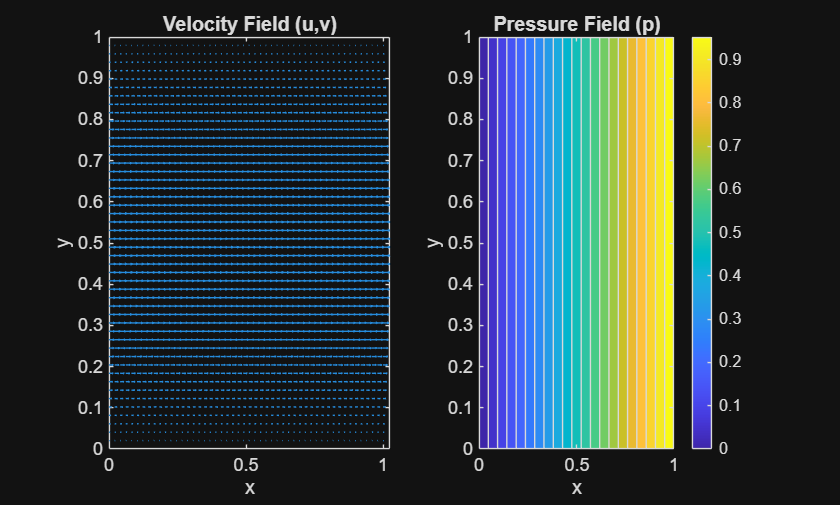

run("generate.m")

## Preprocess for PINN

run("preprocessdata.m")

## Load Processed Data

load("preprocessedData.mat")

## Create PINN

net = createPINN();

## Train PINN

net = trainPINN(net, inputs, targets);


=== Starting PINN Training ===


## Visualize PINN Prediction

plotResults(net, inputs(:,1), inputs(:,2), X, Y);